# ACO Assignment 2022 Q3 H Infinity Controller

## Load Linearized State-space plant

clc 
clear 
load linearizedModel_Outputs.mat


## Define some variables for use

s = zpk('s') %for defining transfer functions

s =
 
  s
 
Continuous-time zero/pole/gain model.



om_rad = logspace(-2,5,1001); %define logspace range for plotting bode plot
om_rad_lin = linspace(0.5,3,1001); %define range for plotting highlight of frequency range

bw_gamma_rad = 0.2*2*pi %define target azimuth motion bandwith, 2pi radians is one hertz

bw_gamma_rad = 1.2566

bw_alpha_rad = 0.25*2*pi %define target elevation motion bandwith, 2pi radians is one hertz

bw_alpha_rad = 1.5708

##  Look at the plant

% figure(1)
% bode(P_ss_self, om_rad)
% grid on


## Singular Value

% figure(2)
% subplot(1,2,1)
% sigma(P_ss_self,om_rad)
% legend
% grid on
% subplot(1,2,2)
% sigma(P_ss_self,om_rad_lin)
% legend
% grid on

% rng(0,'twister'); % For reproducibility
% H = rss(4,2,3);
% bode(H)
% grid on
% sigma(H)
% legend
% grid on

## Design the weights individually then combine them

%Penalize high frequency input from the actuator
W_Vgamma = 1;%same importance, no bandwidth limit for control signal, yet
W_Valpha = 1;%same importance

Wi =mdiag(W_Vgamma,W_Valpha);
Wi = ss(Wi);

Wo11 = 20e-2/(s + 6*bw_gamma_rad);%1*bw_gamma_rad
Wo22 = 40e-2/(s + 6*bw_alpha_rad); %0.1*bw_alpha_rad
Wo = mdiag(Wo11,Wo22);
Wo = ss(Wo);


## Form the Weighted Plant

Pw = Wo*P_ss_self*Wi;

## Check the weighted plant with sigma

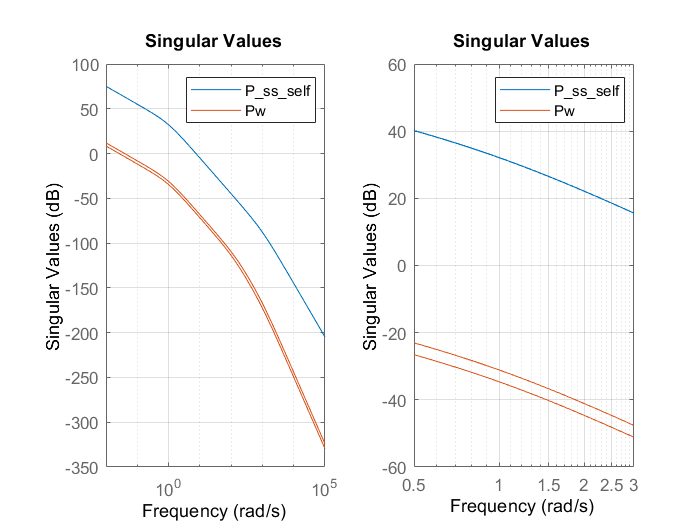

figure(3)
clf
subplot(1,2,1)
sigma(P_ss_self,Pw,om_rad)
legend
grid on
subplot(1,2,2)
sigma(P_ss_self,Pw,om_rad_lin)
legend
grid on

## Check the weight plant with bode

% figure(4)
% bode(P_ss_self,Pw,om_rad)
% 
% legend
% grid on


## Check the robustness with rho, v-gap

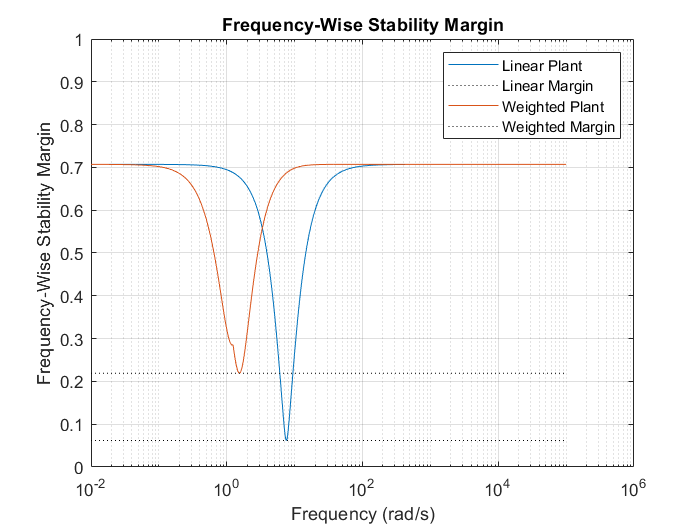

figure(5)
clf
rho(P_ss_self, -eye(2),om_rad)
hold on
rho(Pw, -eye(2),om_rad)
grid on
legend('Linear Plant','Linear Margin','Weighted Plant','Weighted Margin')
hold off

## Check robustness with diskmargin

DM_P = diskmargin(P_ss_self)

DM_P = 2×1 struct array with fields:
    GainMargin
    PhaseMargin
    DiskMargin
    LowerBound
    UpperBound
    Frequency
    WorstPerturbation


DGM_P_alpha = DM_P(2).GainMargin

DGM_P_alpha =     0.8830    1.1325


DGM_P_gamma = DM_P(1).GainMargin

DGM_P_gamma =     0.8826    1.1330



DGMAll_P = [DGM_P_gamma;DGM_P_alpha];



DM_Pw = diskmargin(Pw)

DM_Pw = 2×1 struct array with fields:
    GainMargin
    PhaseMargin
    DiskMargin
    LowerBound
    UpperBound
    Frequency
    WorstPerturbation


DGM_Pw_alpha = DM_Pw(2).GainMargin

DGM_Pw_alpha =     0.6332    1.5792


DGM_Pw_gamma = DM_Pw(1).GainMargin

DGM_Pw_gamma =     0.5420    1.8452



DGMAll_Pw = [DGM_Pw_gamma;DGM_Pw_alpha;DGM_P];


## Plot the diskmargins

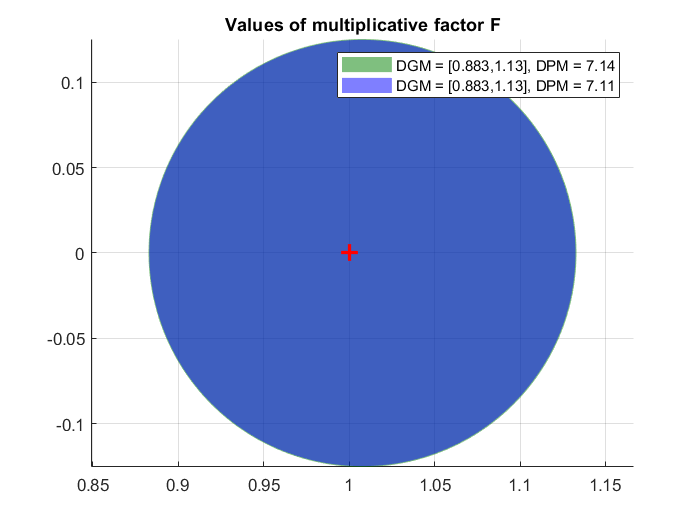

figure(6)
clf
diskmarginplot(DGMAll_P,'disk')


figure(7)
title('test')

Cannot find an exact (case-sensitive) match for 'Title'

The closest match is: title in C:\Program Files\MATLAB\R2021a\toolbox\matlab\graph2d\title.m

clf
subplot(2,2,1)
diskmarginplot(DGM_P_gamma,'nyquist')
subplot(2,2,2)
diskmarginplot(DGM_P_alpha,'nyquist')
subplot(2,2,3)
diskmarginplot(DGM_Pw_gamma,'nyquist')
subplot(2,2,4)
diskmarginplot(DGM_Pw_alpha,'nyquist')